% figure out how this function works
% trainset = [1,2,3,4,5,6,7,8,9]';
% rawData = [1 2 3]';
% p = 2;
% [TrainData,TrainTarget]=getTimeSeriesTrainData(trainset, p);

load lasertrain.dat
load laserpred.dat

% standardize the datasets

trainset = DataStandardization(lasertrain);
predset = DataStandardization(laserpred);


% get time series train data
p = 2; % define the number of lags
% get the training data 
[TrainData,TrainTarget]=getTimeSeriesTrainData(trainset, p);

[trainInd,valInd,testInd] = divideblock(size(TrainData,2),0.6,0.2,0.2);

% training set 
x_train = TrainData(:,trainInd);
t_train = TrainTarget(:,trainInd);

% validation set 
x_val = TrainData(:,valInd);
t_val = TrainTarget(:,valInd);

% test set 

x_test = TrainData(:,testInd);
t_test = TrainTarget(:,testInd);


% Configuration

% traingd gradient descent
% traingda gradient descent with adaptive learning rate
% traincgf Fletcher-Reeves conjugate gradient algorithm
% traincgp Polak-Ribiere conjugate gradient algorithm
% trainbfg - BFGS (quasi Newton)
% trainlm - Levenberg - Marquardt
alg = 'trainlm';% First training algorithm to use
H = 50;% Number of neurons in the hidden layer
delta_epochs = [1,14,85];% Number of epochs to train in each step
epochs = cumsum(delta_epochs);

% Creation of network
% net=feedforwardnet(H,alg);

Attempt to execute SCRIPT feedforwardnet as a function:
C:\Users\ASUS\Documents\MATLAB\ANN Exercise 2\feedforwardnet.mlx

% configure the transfer function 
% logsig
% tansig
% pureline
net.layers{1}.transferFcn = 'tansig';
net=configure(net,x_train,t_train);% Set the input and output sizes of the net
net.divideFcn = 'dividetrain';% Use training set only (no validation and test split)
net=init(net);% Initialize the weights (randomly)

%training 
net.trainParam.epochs=delta_epochs(1);  % set the number of epochs for the training 
net=train(net,x_train,t_train);   % train the networks

% estimate the target using train network with train, val, test set
t1=sim(net,x_train);
v1=sim(net,x_val);
a1=sim(net,x_test);


net.trainParam.epochs=delta_epochs(2);  % set the number of epochs for the training 
net=train(net,x_train,t_train);   % train the networks

% estimate the target using train network with train, val, test set
t2=sim(net,x_train);
v2=sim(net,x_val);
a2=sim(net,x_test);


net.trainParam.epochs=delta_epochs(3);  % set the number of epochs for the training 
net=train(net,x_train,t_train);   % train the networks

% estimate the target using train network with train, val, test set
t3=sim(net,x_train);
v3=sim(net,x_val);
a3=sim(net,x_test);

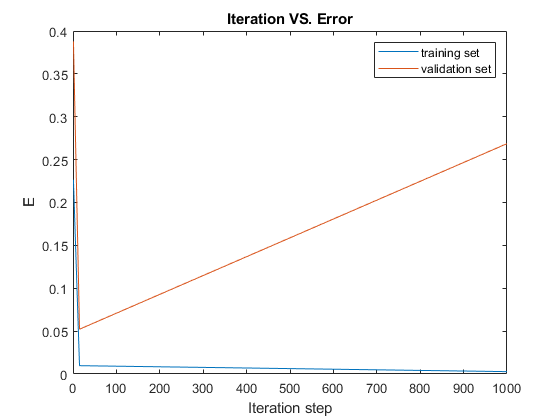

% validation of the network: hyperparameter tuning

% Calculate MSE of the training set 
MSE_t1 = perform(net,t1,t_train);
MSE_t2 = perform(net,t2,t_train);
MSE_t3 = perform(net,t3,t_train);

MSE_Train = [MSE_t1 MSE_t2 MSE_t3];

% Calculate MSE of the validation set 
MSE_v1 = perform(net,v1,t_val);
MSE_v2 = perform(net,v2,t_val);
MSE_v3 = perform(net,v3,t_val);

MSE_Val = [MSE_v1 MSE_v2 MSE_v3];


figure('Name','Iteration VS. Error')

plot(epochs, MSE_Train, epochs, MSE_Val)
legend('training set','validation set');
title('Iteration VS. Error');
xlabel('Iteration step');
ylabel('E');